# 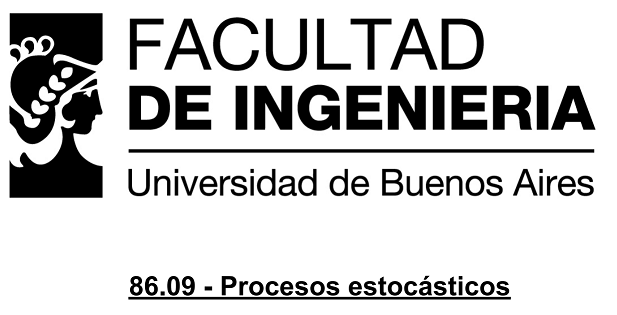

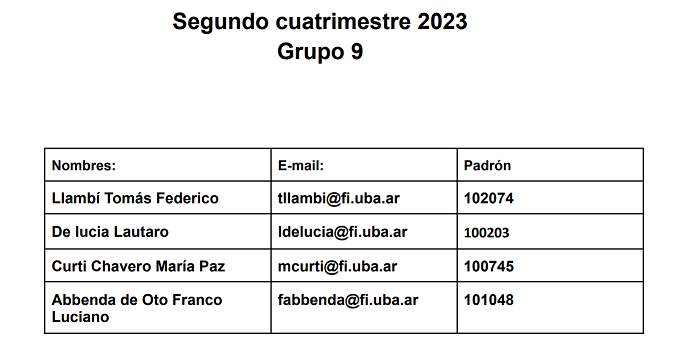

# **TP2 - LINEAR PREDICTIVE CODING**

## **Explicación de la Consigna**

- **Introducción**

**LPC **es una técnica que busca reproducir el habla humana. basandose en el modelado de el tracto vocal de la persona como un filtro $H\left(z\right)$ cuyos coeficientes se extraen de una muestra de audio de la voz a modelar.

- **Modelo**

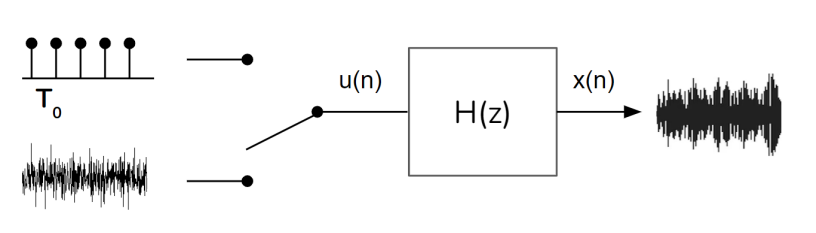

Las vocales se modelan como un trén de impulsos y las consonantes como ruido blanco. El tren de impulsos representa la excitación periódica de las cuerdas vocales durante la producción de sonidos vocálicos como "a" o "e". Mientras que el ruido blanco representa el "ruido" de alta frecuencia que producimos al pronunciar una consonante como "f", "s". Por supuesto, el trén de impulsos no tiene por si mismo "sonido de vocal", sino que es el modelo de el tracto vocal $H\left(z\right)$ el que se encarga de, para cierto período $T_0$ de el tren de impulsos, producir una salida $x\left(n\right)$ que suene como una "a" o una "e".

Las ecuaciones de el modelo van a ser de la forma:

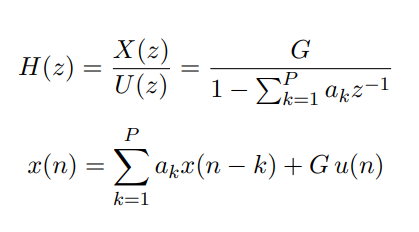

Notamos que $x\left(n\right)$ resulta de una combinación lineal de las muestras anteriores de la señal (término autoregresivo) y la excitación $u\left(n\right)$ modulada por una ganancia $G$.

- **Estimación de **$G$** y **$\vec{a}$

Esta claro que lo que queremos conocer son los coeficientes $a_k$ y la ganancia $G$. Solo con esto alcanza para generar a partir $u\left(n\right)$ tren de impulsos o ruido blanco la *voz* $x\left(n\right)$.

Como asumimos que $x\left(n\right)$ es un proceso auto-regresivo (AR), existe una dependencia temporal donde valores recientes tienen una fuerte influencia sobre los valores actuales. Luego, un valor actual de esta serie temporal puede ser aproximado por una combinación lineal de sus valores anteriores. En suma, es justo asumir que $\hat{x} \left(n\right)=\sum_{k=1}^P a_k x\left(n-k\right)\;$es un buen estimador de $x\left(n\right)$. Relacionandolo con la definición de arriba, tenemos entonces que $e\left(n\right)=x\left(n\right)-\hat{x} \left(n\right)=\textrm{Gu}\left(n\right)$ es el residuo de esta estimación. Aplicando el criterio de minimización de el MSE, que en este caso implica minimizar la potencia de $e\left(n\right)$, podemos llegar a ecuaciones normales de la forma:

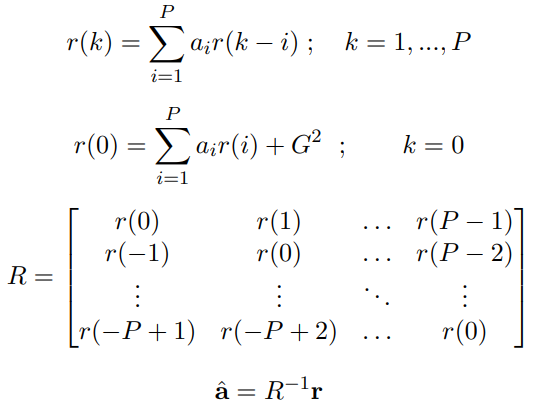

Siendo $r\left(k\right)$ la autocorrelación para $x\left(n\right)$. Podemos despejar $G$ de la segunda ecuación y obtener valores estimados para los coeficientes $a_k$ de la cuarta ecuación.

- **Estimación de el Pitch **$f_0$

El objetivo de la detección de pitch o tono fundamental (representado como $T_0$ en el texto) es identificar la frecuencia a la que vibran las cuerdas vocales durante la producción de sonidos sonoros, particularmente durante las vocales en el canto. 

Cuando hablamos de señales de voz o canto, hay segmentos en los cuales la voz tiene un tono definido, es decir, un patrón periódico, que en el contexto de procesamiento de señales se relaciona con la existencia de un pitch definido. Estos segmentos corresponden generalmente a las vocales al cantar, ya que las cuerdas vocales vibran de manera periódica durante su producción.

Para recrear la señal de voz con precisión en sistemas de codificación de voz o síntesis, es esencial identificar y mapear estos tonos. La idea es que, al reconstruir la voz, se utilice un tren de impulsos $u\left(n\right)$ con un período $T_0$� para representar la frecuencia fundamental de la voz en esos segmentos sonoros. 

No todos los sonidos tienen un tono. Por ejemplo, los susurros no tienen un tono claro. Así que es importante distinguir entre señales sonoras (con tono) y señales sordas (sin tono o más parecido al ruido). El gráfico muestra dos situaciones: en la señal sorda (izquierda), no vemos un pico prominente aparte del centro, lo que significa que no hay un tono claro. Por otro lado, en la señal sonora (derecha), hay un pico claro aparte del centro, indicando la presencia de un tono.

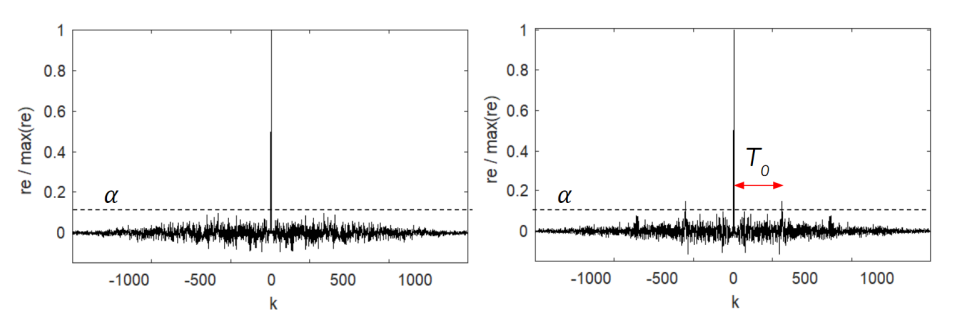

Para decidir si una señal tiene un tono o no, se utiliza un umbral. Si la autocorrelación normalizada excede este umbral en algún punto aparte del centro, se considera que esa señal tiene un tono. En caso contrario, se asume que es más parecido al ruido blanco. Este umbral es una herramienta importante y puede necesitar ajustes dependiendo del contexto.

Existen varios métodos para detectar el pitch, y uno de los más efectivos es el método de Autocorrelación. Básicamente, la autocorrelación mide cómo una señal se parece a sí misma en diferentes puntos en el tiempo. Se busca el patrón repetitivo que representa la frecuencia fundamental del sonido. La fórmula proporcionada muestra cómo calcular este valor utilizando la autocorrelación del residuo de la señal.

- **Codificación de la Señal**

- La señal de habla original se divide en segmentos cortos (de decenas de milisegundos) mediante la multiplicación por una ventana (e.g ventana de Hamming).

- Calculamos, usando la metodología que se ilustra más arriba, $\left\lbrace \vec{a} ,G,f_o \right\rbrace$para cada segmento.

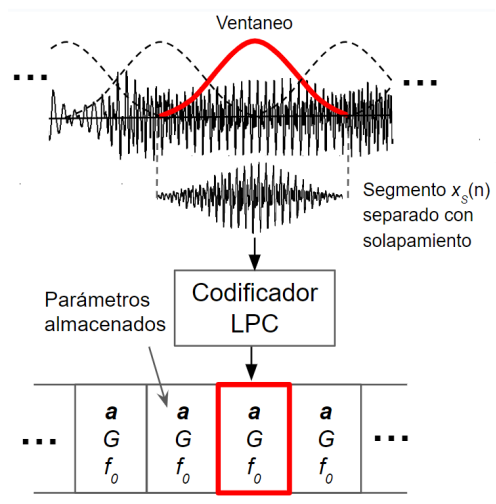

- **De-Codificación de la Señal**

- Para cada segmento, tomamos $\left\lbrace \vec{a} ,G,f_o \right\rbrace$calculado. 

- Construimos el filtro $H\left(z\right)$ utilizando los coeficientes $\vec{a}$ y la ganancia $G$ y construimos la excitación, que puede ser un tren de impulsos con frecuencia $f_0$� (vocales) o ruido blanco (consonantes). 

- Obtenemos los $x\left(n\right)$ para cada segmento y los agregamos (utilizando nuevamente ventaneo para prevenir discontinuidades).

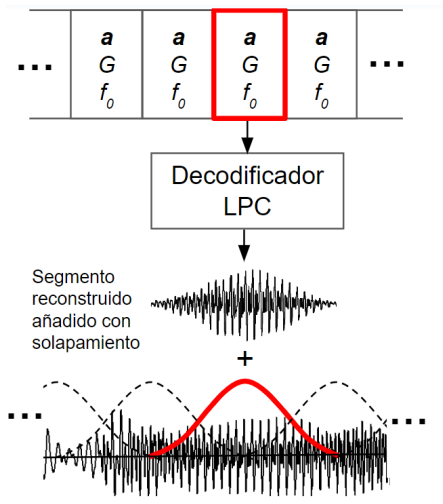

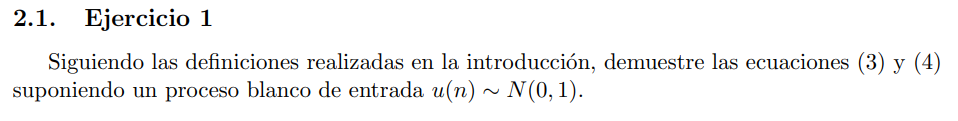

Por definición, la autocorrelación de un proceso $x\left(n\right)$ es de la forma: $r\left(k\right)=E\left\lbrack x\left(n\right)x\left(n-k\right)\right\rbrack$

El estimador propuesto para $x\left(n\right)$ era de la forma $\hat{x} \left(n\right)=\sum_{i=1}^P a_i x\left(n-i\right)\;$

Luego, teníamos un residuo $e\left(n\right)=x\left(n\right)-\hat{x} \left(n\right)$, el cual se minimizaba cuando se verifica ortogonalidad: $E\left\lbrack x\left(n-k\right)e\left(n\right)\right\rbrack =0$

Reemplazando $e\left(n\right)$ en la ecuación: 


$$\begin{array}{l}
E\left\lbrack x\left(n−k\right)\left(x\left(n\right)−\hat{x} \left(n\right)\right)\right\rbrack =E\left\lbrack x\left(n\right)x\left(n−k\right)\right\rbrack −E\left\lbrack x\left(n−k\right)\sum_{i=1}^{P} a_i x\left(n−i\right)\text{ }\right\rbrack =\\
=\text{ }r\left(k\right)−\sum_{i=1}^{P} a_i E\left\lbrack x\left(n−i\right)x\left(n−k\right)\right\rbrack =r\left(k\right)−\sum_{i=1}^{P} a_i r\left(k−i\right)=0
\end{array}$$


Finalmente, llegamos a que:

## 
$$r\left(k\right)=\sum_{i=1}^P a_i r\left(k-i\right)$$


En cuanto a la ecuación (4), notamos que:


$$r\left(k\right)=E\left\lbrack x\left(n\right)x\left(n-k\right)\right\rbrack \to r\left(0\right)=E\left\lbrack x\left(n\right)x\left(n\right)\right\rbrack =E\left\lbrack x^2 \left(n\right)\right\rbrack$$


Donde $x\left(n\right)=\sum_{k=1}^P a_k x\left(n-k\right)+\mathrm{Gu}\left(n\right)\to x^2 \left(n\right)={\left\lbrack \sum_{k=1}^P \;a_k x\left(n-k\right)\right\rbrack }^2 +2\mathrm{Gu}\left(n\right)\sum_{k=1}^P \;a_k x\left(n-k\right)+{\left\lbrack \mathrm{Gu}\left(n\right)\right\rbrack }^2$

- Como $u\left(n\right)=\frac{1}{G}e\left(n\right)$ y, por ortogonalidad, $E\left\lbrack x\left(n-k\right)e\left(n\right)\right\rbrack =0$, el término cruzado se anula.

- Como $u\left(n\right)~N\left(0,1\right)\to E\left\lbrack {\left(\mathrm{Gu}\left(n\right)\right)}^2 \right\rbrack =G^2 E\left\lbrack u^2 \left(n\right)\right\rbrack =\mathrm{GVar}\left(u\left(n\right)\right)=G^2$.

Tenemos entonces que $r\left(0\right)=E\left\lbrack {\left\lbrack \sum_{k=1}^P \;a_k x\left(n-k\right)\right\rbrack }^2 \right\rbrack +G^2$

Notemos que $E\left\lbrack {\left\lbrack \sum_{k=1}^P \;a_k x\left(n-k\right)\right\rbrack }^2 \right\rbrack$=$E\left\lbrack \sum_{i=1}^P \;\sum_{j=1}^P a_i a_j x\left(n-i\right)x\left(n-j\right)\right\rbrack =\sum_{i=1}^P \;a_i \sum_{j=1}^P a_j E\left\lbrack x\left(n-i\right)x\left(n-j\right)\right\rbrack$

Por último, notamos que $\sum_{j=1}^P a_j E\left\lbrack x\left(n-i\right)x\left(n-j\right)\right\rbrack =\sum_{j=1}^P a_j r\left(i-j\right)=r\left(i\right)$ dada  la demostración de la ecuación (3).

Quedando finalmente:

## 
$$r\left(0\right)=\sum_{i=1}^P \;a_i r\left(i\right)+G^2$$


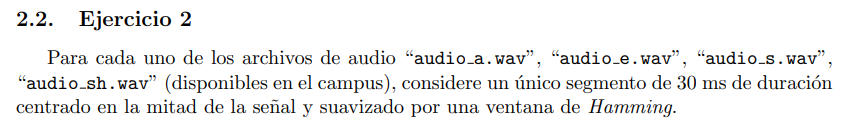

A continuación, se presentan los segmentos suavizados mediante la ventana de Hamming. Es notable que, en el caso de los fonemas 'a' y 'e', la señal muestra una similitud visual más cercana a una onda senoidal o cosenoidal con frecuencia constante. En contraste, para los fonemas 's' y 'sh', la apariencia del ruido se asemeja a la de ruido blanco.

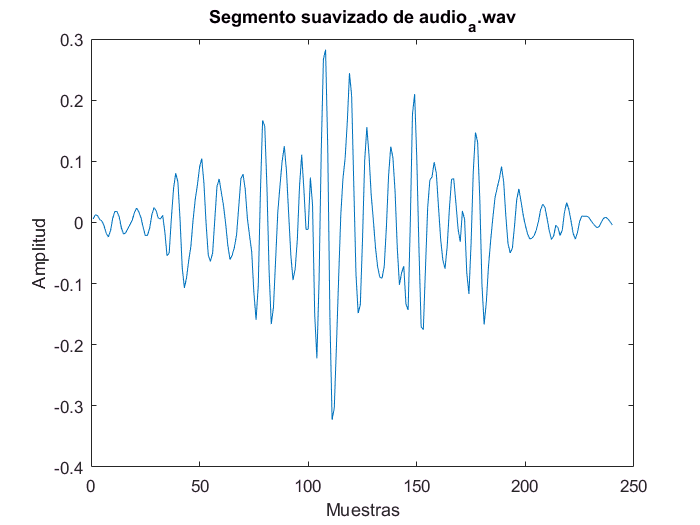

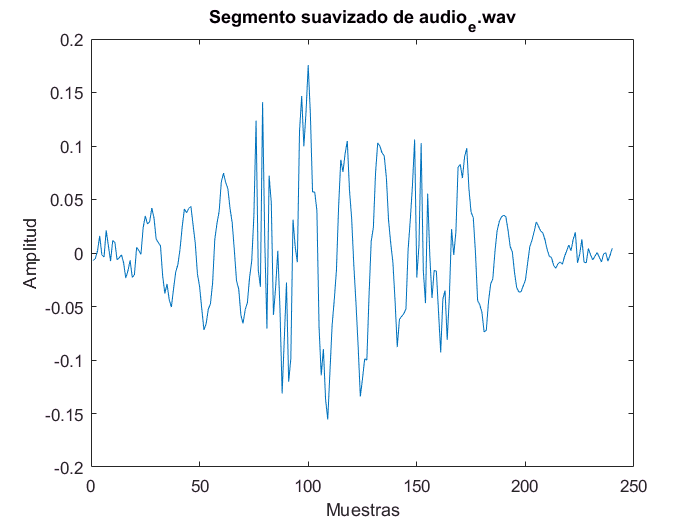

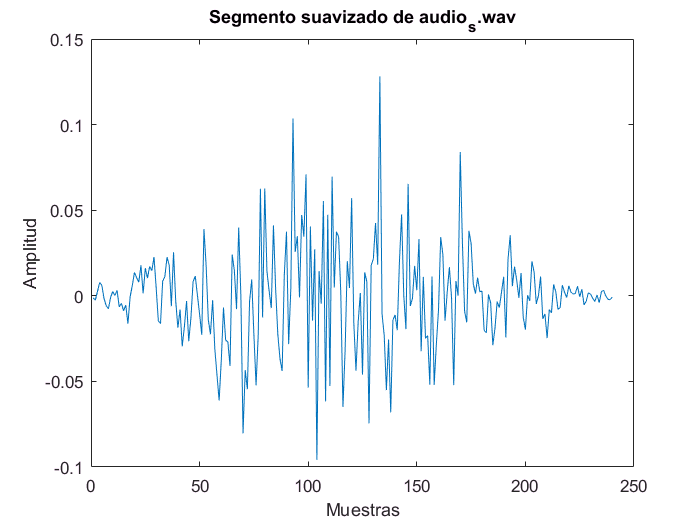

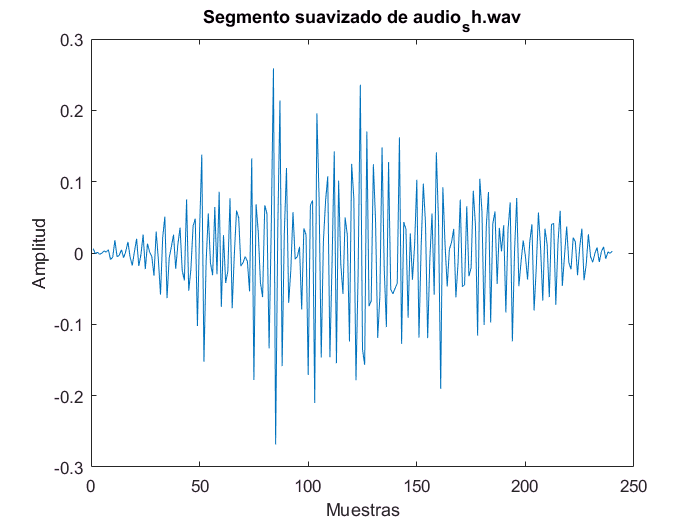

%% Procesamiento de archivos de audio y almacenamiento de segmentos en un arreglo

% Crear un arreglo con los nombres de los archivos de audio
directorio = './audios/'; % Directorio donde se encuentran los archivos
nombres = {'audio_a.wav', 'audio_e.wav', 'audio_s.wav', 'audio_sh.wav'};

% Duración del segmento en segundos
duracion_segmento = 0.03;

% Arreglo para guardar segmentos suavizados
segmentos_ventana = {};

% Procesar cada archivo de audio y guardar segmentos suavizados
for i = 1:length(nombres)
    % Leer archivo de audio
    [y, Fs] = audioread([directorio nombres{i}]);
    
    % Utilizar la función obtener_segmento y guardar en el arreglo
    segmentos_ventana{i} = obtener_segmento(y, Fs, duracion_segmento);
end

% Graficar segmentos guardados
for i = 1:length(nombres)
    figure;
    plot(segmentos_ventana{i});
    title(['Segmento suavizado de ' nombres{i}]);
    xlabel('Muestras');
    ylabel('Amplitud');
end

%% Estimación de parámetros LPC para diferentes órdenes usando segmentos guardados

% Arreglo de órdenes P
diferentes_P = [5, 10, 30];

% Estimar parámetros LPC para diferentes órdenes usando segmentos guardados
for i = 1:length(nombres)
    for j = 1:length(diferentes_P)
        [a, G] = custom_lpc(segmentos_ventana{i}, diferentes_P(j));
        fprintf('Coeficientes LPC para %s con P = %d: \n', nombres{i}, diferentes_P(j));
        disp(a);
        fprintf('Ganancia G para %s con P = %d: %f\n', nombres{i}, diferentes_P(j), G);
    end
end

Coeficientes LPC para audio_a.wav con P = 5: 


    1.0000   -2.0001    2.3205   -1.4928    0.6454   -0.0349



Ganancia G para audio_a.wav con P = 5: 0.020219


Coeficientes LPC para audio_a.wav con P = 10: 


    1.0000   -1.9996    2.3535   -1.5831    0.7946   -0.0990    0.0213   -0.2642    0.6700   -0.6082    0.2112



Ganancia G para audio_a.wav con P = 10: 0.017962


Coeficientes LPC para audio_a.wav con P = 30: 


  Columns 1 through 18

    1.0000   -2.0565    2.4535   -1.3683    0.0217    1.0141   -0.6990   -0.2105    1.1291   -0.6760   -0.5432    1.6385   -1.3856    0.2664    1.1232   -1.4109    0.8887    0.2388

  Columns 19 through 31

   -0.8510    0.8981   -0.2463   -0.2473    0.4502   -0.0407   -0.2880    0.6536   -0.4735    0.0990    0.3313   -0.3305    0.1964



Ganancia G para audio_a.wav con P = 30: 0.013909


Coeficientes LPC para audio_e.wav con P = 5: 


    1.0000   -0.8057    0.2556   -0.7372    0.3386    0.3872



Ganancia G para audio_e.wav con P = 5: 0.020009


Coeficientes LPC para audio_e.wav con P = 10: 


    1.0000   -0.7650    0.4842   -1.2726    0.8126   -0.2296    0.7125   -0.2810    0.0385    0.0155   -0.0356



Ganancia G para audio_e.wav con P = 10: 0.016165


Coeficientes LPC para audio_e.wav con P = 30: 


  Columns 1 through 18

    1.0000   -0.7266    0.6131   -1.3783    0.9296   -0.4245    1.0457   -0.4274    0.3298   -0.3960    0.3079   -0.3246    0.7284   -0.4890    0.6012   -0.6932    0.5976   -0.4592

  Columns 19 through 31

    0.5915   -0.3021    0.3102   -0.1705    0.1996    0.0128    0.1503   -0.0534   -0.0619   -0.0352    0.1021    0.0842    0.1087



Ganancia G para audio_e.wav con P = 30: 0.014132


Coeficientes LPC para audio_s.wav con P = 5: 


    1.0000   -0.1472   -0.1080    0.1037   -0.1852    0.2046



Ganancia G para audio_s.wav con P = 5: 0.027318


Coeficientes LPC para audio_s.wav con P = 10: 


    1.0000   -0.1963   -0.0675    0.1300   -0.2266    0.2710   -0.1540    0.1878    0.1055   -0.1732    0.1801



Ganancia G para audio_s.wav con P = 10: 0.025979


Coeficientes LPC para audio_s.wav con P = 30: 


  Columns 1 through 18

    1.0000   -0.2090   -0.1233    0.1500   -0.2020    0.2103   -0.1808    0.2325    0.0655   -0.1459    0.1049    0.0367   -0.0523   -0.2862    0.0971    0.0819   -0.0117   -0.0700

  Columns 19 through 31

    0.0304   -0.0392   -0.1407    0.0943   -0.0245    0.2145   -0.1003    0.0374    0.2375   -0.1821   -0.0740    0.0608    0.0515



Ganancia G para audio_s.wav con P = 30: 0.023385


Coeficientes LPC para audio_sh.wav con P = 5: 


    1.0000    0.8325    0.8770    0.1249   -0.0132   -0.0690



Ganancia G para audio_sh.wav con P = 5: 0.045378


Coeficientes LPC para audio_sh.wav con P = 10: 


    1.0000    0.8037    0.8534    0.1378    0.0712   -0.0353    0.0199   -0.0399   -0.0300    0.0413   -0.0824



Ganancia G para audio_sh.wav con P = 10: 0.044410


Coeficientes LPC para audio_sh.wav con P = 30: 


  Columns 1 through 18

    1.0000    0.6731    0.8006    0.0946    0.0387    0.0726   -0.0422    0.0457    0.0013    0.1519    0.0048    0.1059    0.0424    0.1779    0.2323    0.0838    0.1284   -0.1238

  Columns 19 through 31

    0.0335    0.0460    0.1032    0.0755   -0.0293   -0.0886    0.0148   -0.1340   -0.0809    0.0183   -0.0381    0.0898   -0.1840



Ganancia G para audio_sh.wav con P = 30: 0.038693


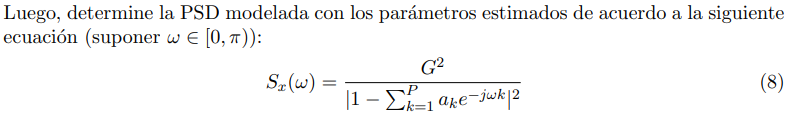

A continuación, se presentan los espectros de densidad espectral de potencia (PSD) de los cuatro fonemas. En el gráfico correspondiente a la vocal 'a', se destaca una predominancia de frecuencias en el rango de 0.5 a 1 rad/segundo. En el caso de la vocal 'e', se observa una situación similar, con dos picos notables alrededor de 0.4 y 1.7 rad/segundo. Estos patrones coinciden con las características esperadas para estos fonemas, que exhiben frecuencias constantes en el tiempo.

Por otro lado, al analizar el PSD del fonema 's', se aprecia que los valores son relativamente uniformes en prácticamente todas las frecuencias ω, lo que se asemeja a la respuesta de una señal de ruido blanco. En contraste, el fonema 'sh' muestra similitudes con 's', pero con una mayor atenuación en las frecuencias más bajas.

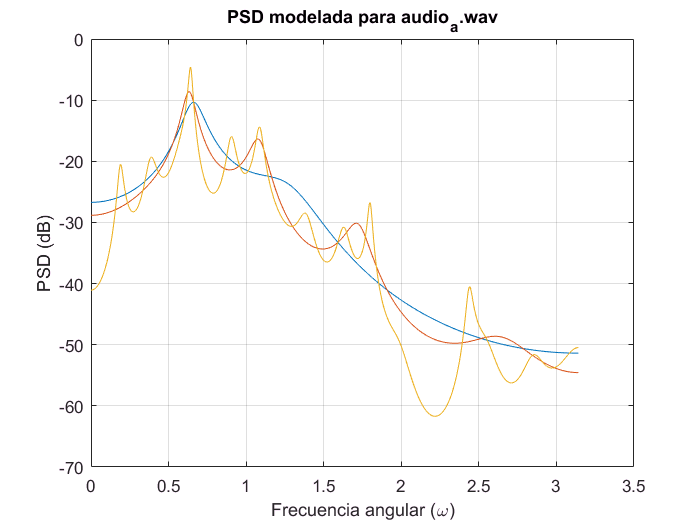

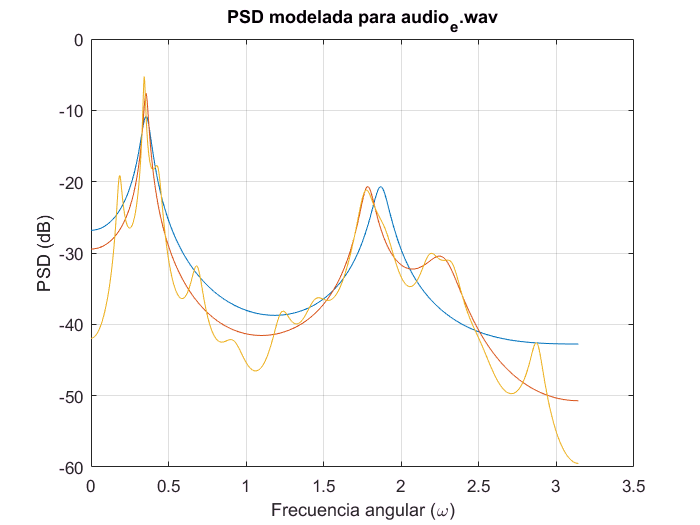

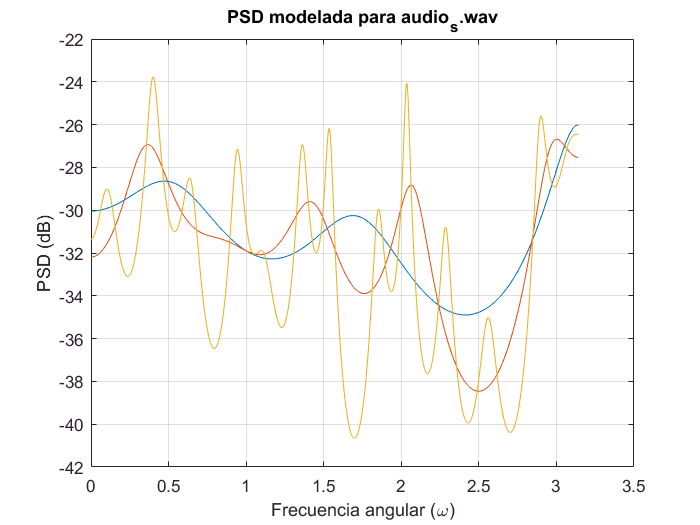

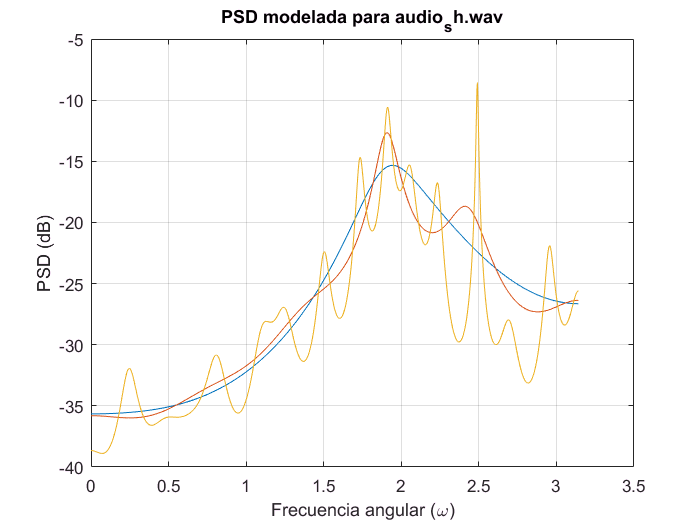

% Rango de frecuencia angular
omega = linspace(0, pi, 1000);

% Calcular y graficar la PSD modelada para cada archivo de audio y diferentes órdenes P
for i = 1:length(nombres)
    figure;
    for j = 1:length(diferentes_P)
        [a, G] = custom_lpc(segmentos_ventana{i}, diferentes_P(j));
        Sx = modeled_PSD(a, G, omega);
        plot(omega, 10*log10(Sx), 'DisplayName', ['P = ' num2str(diferentes_P(j))]);
        hold on;
    end
    title(['PSD modelada para ' nombres{i}]);
    xlabel('Frecuencia angular (\omega)');
    ylabel('PSD (dB)');
    legend;
    grid on;
end

Con la diferencia de tiempo entre el máximo pico de potencia y el segundo pico de mayor potencia podemos determinar el periodo fundamental T0, que está relacionado con la frecuencia fundamental (f0) de la señal de habla. De esta manera podemos identificar y caracterizar las frecuencias fundamentales en los fonemas 'a' y 'e', que tienden a mostrar una apariencia más cercana a una onda senoidal o cosenoidal con frecuencia constante. Para el caso de 'a' obtenemos un T0 de aproximadamente 63 muestras, para 'e' obtenemos 17.

Por otro lado, los fonemas 's' y 'sh' exhiben características que se asemejan a ruido blanco en sus PSD, ya que presentan una distribución uniforme de potencia. Para distinguir entre señales sonoras y sordas, se aplica un método de normalización y se compara el segundo pico más alto con un umbral. Si el segundo pico supera el umbral, se asume una excitación periódica, lo que es especialmente relevante para los fonemas 's' y 'sh', donde la presencia de ruido blanco es más evidente.

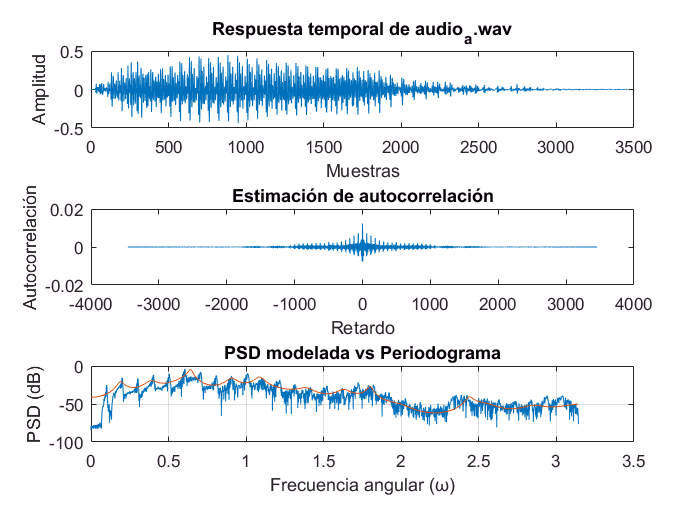

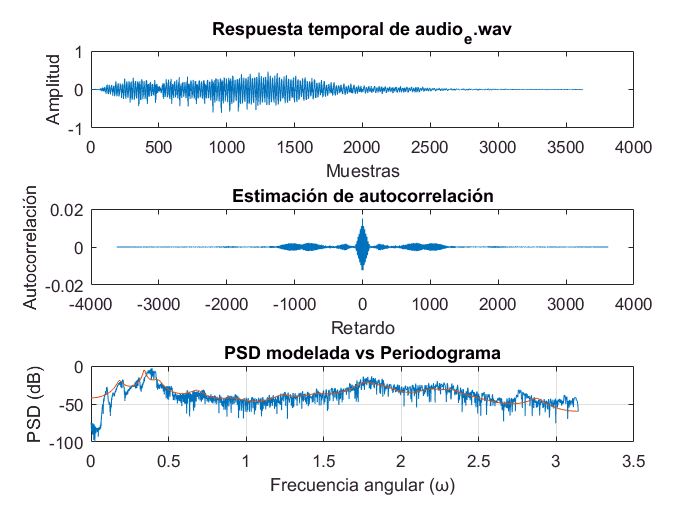

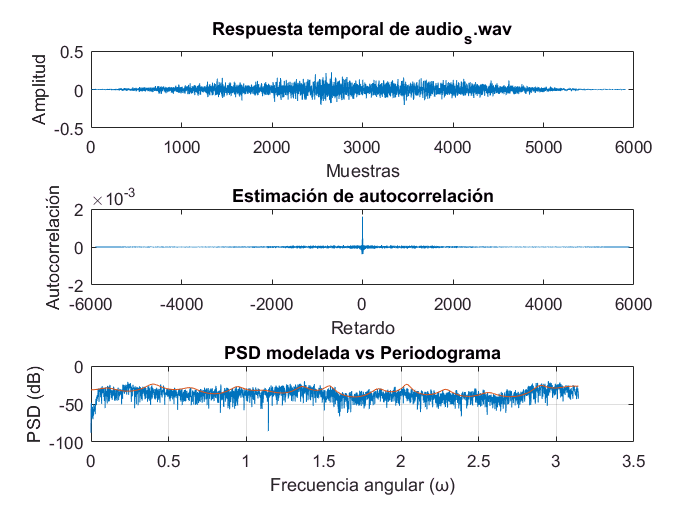

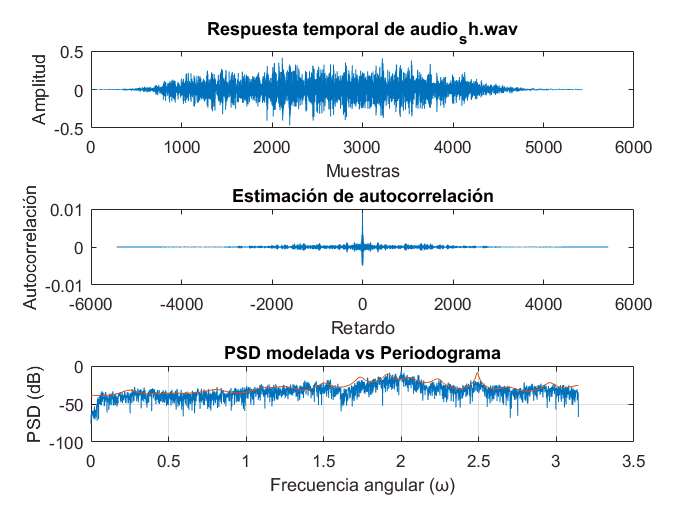

%% Graficar respuesta temporal, autocorrelación y PSD modelada (corregido)

for i = 1:length(nombres)
    % Leer archivo de audio
    [y, Fs] = audioread([directorio nombres{i}]);
    
    % Graficar respuesta temporal
    figure;
    subplot(3,1,1);
    plot(y);
    title(['Respuesta temporal de ' nombres{i}]);
    xlabel('Muestras');
    ylabel('Amplitud');
    
    % Graficar autocorrelación
    subplot(3,1,2);
    [R, lags] = xcorr(y, 'biased');
    plot(lags, R);
    title('Estimación de autocorrelación');
    xlabel('Retardo');
    ylabel('Autocorrelación');
    
    % Graficar PSD modelada superpuesta al periodograma
    subplot(3,1,3);
    [Pxx, f] = periodogram(y, [], 'onesided', Fs); % Calcula el periodograma para f en [0, Fs/2)
    plot(f, 10*log10(Pxx), 'DisplayName', 'Periodograma');
    hold on;
    [a, G] = custom_lpc(segmentos_ventana{i}, 30); % Usar P=10 como ejemplo
    Sx = modeled_PSD(a, G, f);
    plot(f, 10*log10(Sx), 'DisplayName', 'PSD modelada');
    title('PSD modelada vs Periodograma');
    xlabel('Frecuencia angular (ω)');
    ylabel('PSD (dB)');
    legend;
    grid on;
end

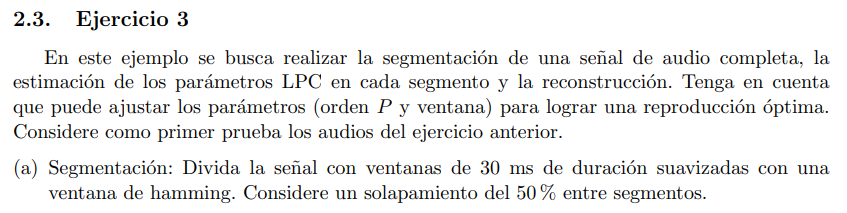

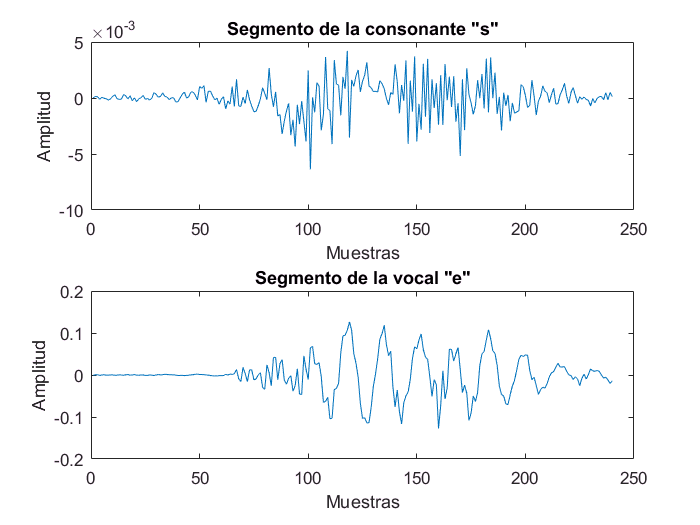

% Consonante 's'
[y_s, Fs] = audioread('./audios/audio_s.wav');
segmentos_s = obtener_segmentos(y_s, Fs, 0.03, 0.5);
% Vocal 'e'
[y_e, Fs] = audioread('./audios/audio_e.wav');
segmentos_e = obtener_segmentos(y_e, Fs, 0.03, 0.5);
% Comparación visual de ambos
seg = 1;
% Seleccionar el primer segmento de cada audio
segmento_s = segmentos_s{seg};
segmento_e = segmentos_e{seg};
% Graficar ambos segmentos
figure;
% Graficar segmento de la consonante 's'
subplot(2,1,1);
plot(segmento_s);
title('Segmento de la consonante "s"');
xlabel('Muestras');
ylabel('Amplitud');
% Graficar segmento de la vocal 'e'
subplot(2,1,2);
plot(segmento_e);
title('Segmento de la vocal "e"');
xlabel('Muestras');
ylabel('Amplitud');

% Definir el orden del modelo LPC
P = 200; % Puede ajustarse según las necesidades

% Inicializar arreglos para almacenar coeficientes y ganancias
coeficientes_s = cell(1, length(segmentos_s));
G_s = zeros(1, length(segmentos_s));
coeficientes_e = cell(1, length(segmentos_e));
G_e = zeros(1, length(segmentos_e));

% Obtener coeficientes y ganancia para cada segmento de 's'
for i = 1:length(segmentos_s)
    [a, G] = custom_lpc(segmentos_s{i}, P);
    coeficientes_s{i} = a;
    G_s(i) = G;
end

% Obtener coeficientes y ganancia para cada segmento de 'e'
for i = 1:length(segmentos_e)
    [a, G] = custom_lpc(segmentos_e{i}, P);
    coeficientes_e{i} = a;
    G_e(i) = G;
end

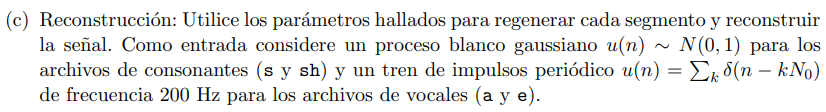

Observamos que la reconstrucion es bastante buena aunque no identica, esto se vera reflejado claramente en el audio aunque es lo suficientemente bueno para que se pueda entender aun siendo un fonema aislado.

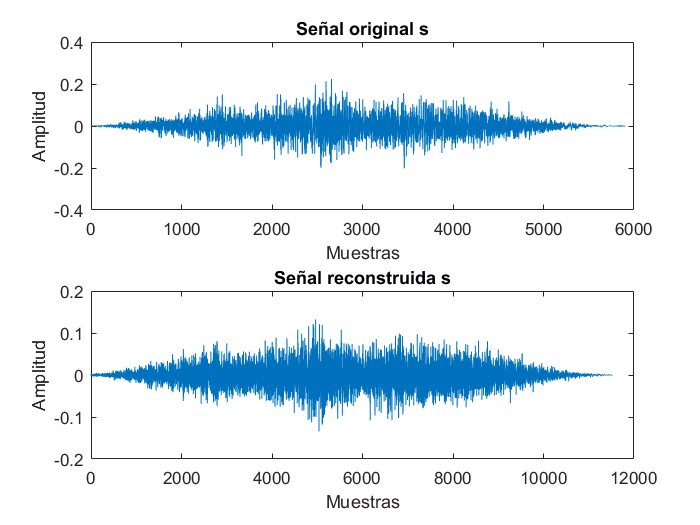


% Reconstruir señal para 's'
y_reconstruido_s = reconstruir_senal(coeficientes_s, G_s, 'consonante', Fs, 0.03);

% Reconstruir señal para 'e'
y_reconstruido_e = reconstruir_senal(coeficientes_e, G_e, 'vocal', Fs, 0.03);

% Graficar señal original y reconstruida para 's'
figure;
subplot(2,1,1);
plot(y_s);
title('Señal original s');
xlabel('Muestras');
ylabel('Amplitud');

subplot(2,1,2);
plot(y_reconstruido_s);
title('Señal reconstruida s');
xlabel('Muestras');
ylabel('Amplitud');

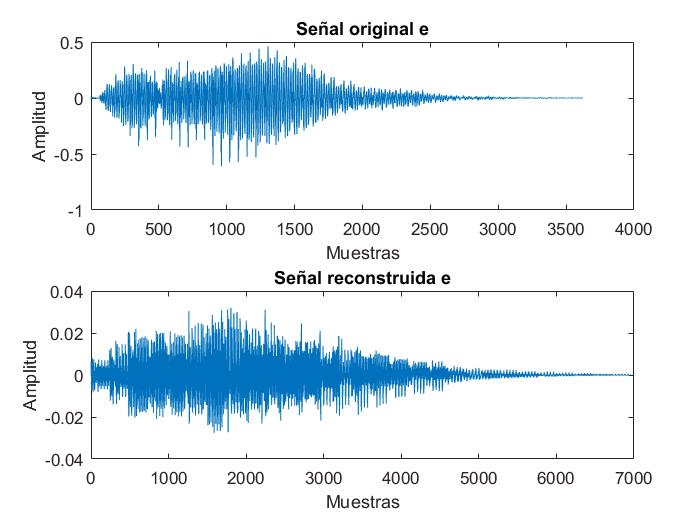


% Graficar señal original y reconstruida para 'e'
figure;
subplot(2,1,1);
plot(y_e);
title('Señal original e');
xlabel('Muestras');
ylabel('Amplitud');

subplot(2,1,2);
plot(y_reconstruido_e);
title('Señal reconstruida e');
xlabel('Muestras');
ylabel('Amplitud');

Al escuchar los audios se puede entender cual es el contenido de los mismos aunque la voz se escucha bastante robotica, para mejorar esto se aumento el orden del estimador lo maximo posible obteniendo resultados bastante buenos. Es notable que a ordenes de P bajos la inteligibilidad se mantiene pero se aleja mucho de el audio original en cuanto al timbre de la voz, en ordenes más grandes se mejora un poco este aspecto. En nuestro caso con P = 200  obtuvimos muy buenos resultados.

% Exportar señal original 's' a archivo WAV
audiowrite('original_s.wav', y_s, Fs);

% Exportar señal reconstruida 's' a archivo WAV
y_reconstruido_s_atenuado = y_reconstruido_s / (10 * rms(y_reconstruido_s));
audiowrite('reconstruido_s.wav', y_reconstruido_s_atenuado, Fs);

% Repetir para 'e'...
audiowrite('original_e.wav', y_e, Fs);
y_reconstruido_e_atenuado = y_reconstruido_e / (10 * rms(y_reconstruido_e));
audiowrite('reconstruido_e.wav', y_reconstruido_e_atenuado, Fs);



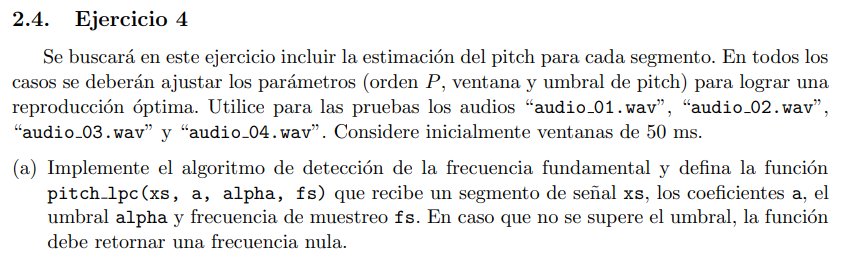

Finalmente, encontramos que para una reproducion optima los parametros deben ser los siguientes:

- Duracion de segmentos: 35ms

- Solapamiento: 100ms

- Orden del estimador: 200

- Alpha: 0.9

Con estos parametros se reconstruyen audios inteligibles, aunque también tiene ciertos ruidos no deseados estan relacinados con el ancho del segmento y su solapamiento. Concluimos que aunque el metodo es muy interesante aun quedan muchos ajustes por realizar para obtener resultados de mejor calidad.

% Cargar la señal de audio 'audio_01.wav'
[y, Fs] = audioread('./audios/audio_01.wav');

% Obtener sus segmentos
duracion_segmento = 0.035; % 30 ms
solapamiento = 0.1; % 50% de solapamiento
segmentos = obtener_segmentos(y, Fs, duracion_segmento, solapamiento);

% Obtener los coeficientes a_k y la ganancia G para cada segmento
P = 200; % Orden del predictor LPC (puedes ajustar este valor según necesites)
coeficientes = cell(length(segmentos), 1);
G = zeros(length(segmentos), 1);
for i = 1:length(segmentos)
    [a, g] = custom_lpc(segmentos{i}, P);
    coeficientes{i} = a;
    G(i) = g;
end

% Obtener la frecuencia fundamental para cada segmento
alpha = 0.9; % Umbral (puedes ajustar este valor según necesites)
f0 = zeros(length(segmentos), 1);
for i = 1:length(segmentos)
    f0(i) = pitch_lpc(segmentos{i}, coeficientes{i}, alpha, Fs);
end

% Reconstruir la señal
y_reconstruido = reconstruir_senal_v2(coeficientes, G, f0, Fs, duracion_segmento);

% Exportar la señal reconstruida
audiowrite('audio_01_reconstruido.wav', y_reconstruido, Fs);


## Conclucion:

Pudimos realizar la reconstruccion de la voz de manera optima dentro de los limites del modelo, alcanzando una buena inteligibilidad de la palabra y un timbre de voz que se asemeja al original. Es posible que con más ajustes se puedan conseguir mejores resultados aunque posiblemente metodos mas avanzados den mejores resultados.